# **Movimento Quadrato**

La prima cosa che vado a fare è definire una funzione di **cinematica inversa **per andare a posizionare il robot nel punto desiderato


function [angoli] = cinematica_inversa(l1,l2,l3,px, py, verso)
    
    %funzione che implementa la cinematica inversa dove
    %l1, l2, l3 sono le lunghezze dei tre bracci e
    %px e py le coordinate del punto in cui si vuole portare il robot
    %restituisce un vetore di angoli, corrispondenti alle variabili di 
    %giunto q1, q2, q3

    
    %dal momento che il vettore degli angoli ci restituisce q1,q2 e q3
    %è importante specificare che per come è sto definito il problema 

    %la prima cosa che si deve andare a fare è capire se il sistema 
    %ammette soluzioni, dunque se il punto che abbiamo come destinazione
    %è all'interno dello spazio su cui andiamo a lavorare
    if sqrt(px^2+py^2) > (l1+l2+l3)
        disp("il punto (py,px) è fuori dal range di lavoro")
        return
    end

    if l2<l1 && (sqrt(px^2+py^2) < (l1-l2))
        disp("il punto (py,px) è fuori dal range di lavoro")
        return
    end

    
    c2=(px^2+py^2-l2^2-l1^2)/(2*l1*l2);
    
    s2=sqrt(1-c2^2); % in verità qui si potrebbe usare anche =-sqrt(1-c2^2)
    %questo dipende se si preferisce una soluzione a gomito alto o a gomito
    %basso

    c1s1=(1/(l1^2+l2^2+2*l1*l2*c2))*[l1+l1*c2 , l2*s2; -l2*s2, l1+l2*c2]*[px;py];
    
    c1= c1s1(1:1);
    s1=c1s1(2:2);
    q1=atan2(s1,c1);
    q2=atan2(s2,c2);

    %per sapere se ci stiamo spostando perpendicolarmente
    %al lato verticale o a quello orizzontale
    if verso == 'lato' 
        q3 = -q1 - q2; 
    elseif verso == 'alto'
        q3 = -pi/2 - q1 - q2;
    end
    
    angoli = [q1,q2,q3];

end

Diamo in pasto alla funzione le proprietà del robot, dunque la lunghezza dei bracci, e le coordinate del punto : (0.2, 0.3)

l1 = 1;
l2 = 1;
l3 = 0.1;
px = 0.2; 
py = 0.3;
cinematica_inversa(l1,l2,l3,px,py, 'lato')

ans =    -0.4067    2.7791   -2.3723


Ora che conosciamo le variabili di giunto del robot nella posiziome iniziale, non resta che andare a valutare come questi cambiano nel tempo per il movimento che i bracci devono compiere; il primo movimento da fare segue un segmento verticale che arriva fino al punto (0.3, 0.7), scriviamo dunque una nuova funzione che andrà a prendere la parametrizzazione del percorso da fare e ci restituirà le velocità con cui si muove il robot. Per farlo dobbiamo andare a tenere conto della matrice jacobiana del robot che è la seguente : 

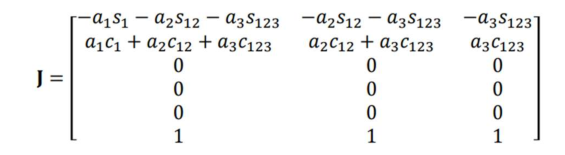

Scriviamo il codice : 



function [angoli, vel, tempo] = movimenti(P1, P2, l1, l2, l3, verso)
    %istanzio i tempi 
    t_inizio = 0; 
    stepTime = 0.1;  
    t_fine = 1.5;
    tempo = t_inizio:stepTime:t_fine; 
    durata = t_fine - t_inizio;
    %normalizzo il tempo 
    tau = (tempo - t_inizio) / durata;
    %implemento la legge oraria
    lambda = 3*tau.^2 - 2*tau.^3;

    angoli = zeros(length(lambda), 3);
    vel = zeros(length(lambda), 3);

    %mi calcolo con la funzione di cinematica inversa le configurazioni dei
    %giunti 
    for i = 1:length(lambda)
        %parametrizzazione del segmento 
        p = P1 + lambda(i)*(P2 - P1);
        angoli(i,:) = cinematica_inversa(l1, l2, l3, p(1), p(2), verso);
    end
    
    %istanzio la derivata che mi servirà poi per la velocità 
    dq_dt = zeros(size(angoli));
   
    for i = 2:length(angoli)-1
        dq_dt(i,:) = (angoli(i+1,:) - angoli(i-1,:)) / (2*stepTime);
    end
    
    dq_dt(1,:) = 0;
    dq_dt(end,:) = 0;

    for i = 1:length(lambda)
        %per una questione di leggibilità 
        q1 = angoli(i,1); q2 = angoli(i,2); q3 = angoli(i,3);
        %preparo la jacobiana
        J = [ l1*sin(q1) - l2*sin(q1+q2) - l3*sin(q1+q2+q3), -l2*sin(q1+q2) - l3*sin(q1+q2+q3), -l3*sin(q1+q2+q3);
              l1*cos(q1) + l2*cos(q1+q2) + l3*cos(q1+q2+q3),  l2*cos(q1+q2) + l3*cos(q1+q2+q3),  l3*cos(q1+q2+q3);
              0, 0, 0; 
              0, 0, 0;
              0, 0, 0;
              1, 1, 1 ];
        v_cartesiane = J * dq_dt(i,:)';
        %ottengo le velocità 
        vel(i,:) = [v_cartesiane(1:2)' v_cartesiane(6)];
    end
end



function [angoli, vel, tempo] = movimenti_rotoazionali(xe, ye, l1, l2, l3, orientamento)
    %istanzio il tempo 
    t_inizio = 0; 
    stepTime = 0.1;  
    t_fine = 1.5;
    tempo = t_inizio : stepTime : t_fine; 
    durata = t_fine - t_inizio;
    tau = (tempo - t_inizio) / durata;
    %legge oraria
    lambda = 3*tau.^2 - 2*tau.^3;

    %scelgo come farlo girare
    if orientamento == 0
        theta = pi - (pi/2) * lambda;
    elseif orientamento == 1
        theta = pi/2 - ((3*pi)/2) * lambda;
    end 
    
    %legge oraria
    px = xe + l3 * cos(theta); 
    py = ye + l3 * sin(theta); 

    %preparo i vettori
    angoli = zeros(length(lambda), 3);
    vel = zeros(length(lambda), 3);

    for i = 1:length(lambda)
        x3 = px(i); y3 = py(i);
        dx = xe - x3; dy = ye - y3;
        q3 = atan2(dy, dx);
        [q1, q2] = ik_2link(x3, y3, l1, l2);
        angoli(i,:) = [q1, q2, q3 - q1 - q2];
    end

    dq_dt = zeros(size(angoli));
    for i = 2:length(angoli)-1
        dq_dt(i,:) = (angoli(i+1,:) - angoli(i-1,:)) / (2*stepTime);
    end
    dq_dt(1,:) = 0;
    dq_dt(end,:) = 0;

    for i = 1:length(lambda)
        q1 = angoli(i,1); q2 = angoli(i,2); q3 = angoli(i,3);
        J = [ l1*sin(q1) + l2*sin(q1+q2) + l3*sin(q1+q2+q3), ...
              l2*sin(q1+q2) + l3*sin(q1+q2+q3), l3*sin(q1+q2+q3);
             -l1*cos(q1) - l2*cos(q1+q2) - l3*cos(q1+q2+q3), ...
             -l2*cos(q1+q2) - l3*cos(q1+q2+q3), -l3*cos(q1+q2+q3);
              0, 0, 1 ];
        vel(i,:) = J * dq_dt(i,:)';
    end
end


% IK per braccio planare a 2 link
function [q1, q2] = ik_2link(x, y, l1, l2)
    r = sqrt(x^2 + y^2);
    cos_q2 = (r^2 - l1^2 - l2^2) / (2 * l1 * l2);
    sin_q2 = sqrt(1 - cos_q2^2);  % gomito giù
    q2 = atan2(sin_q2, cos_q2);

    k1 = l1 + l2 * cos(q2);
    k2 = l2 * sin(q2);
    q1 = atan2(y, x) - atan2(k2, k1);
end


%funzione per animare il robot 

function animazione_robot_planare(angoli, l1, l2, l3)
    % angoli: matrice n x 3 dove ogni riga è [theta1, theta2, theta3]

    figure;
    axis equal;
    axis([-1 1 -1 1]); % adatta in base alla tua workspace
    xticks(-1:0.1:1);
    yticks(-1:0.1:1);
    grid on;
    hold on;

    % Colori
    colore_braccio = 'k';
    colore_giunti = 'ro';
    colore_traiettoria = 'b*';
    colore_orientamento = 'g';

    % Per salvare la traiettoria dell’end-effector
    traiettoria_x = [];
    traiettoria_y = [];

    for i = 1:size(angoli,1)
        q = angoli(i,:);

        % Cinematica diretta per trovare i punti dei giunti
        theta1 = q(1); theta2 = q(2); theta3 = q(3);

        x1 = l1 * cos(theta1);
        y1 = l1 * sin(theta1);

        x2 = x1 + l2 * cos(theta1 + theta2);
        y2 = y1 + l2 * sin(theta1 + theta2);

        x3 = x2 + l3 * cos(theta1 + theta2 + theta3);
        y3 = y2 + l3 * sin(theta1 + theta2 + theta3);

        % Memorizza traiettoria
        traiettoria_x(end+1) = x3;
        traiettoria_y(end+1) = y3;

        % Cancella frame precedente
        cla;

        % Disegna i link
        plot([0 x1 x2 x3], [0 y1 y2 y3], 'o-', 'Color', colore_braccio, 'MarkerFaceColor', 'r', 'LineWidth', 2);

        % Disegna traiettoria dell’end-effector
        plot(traiettoria_x, traiettoria_y, colore_traiettoria);

        % Disegna orientamento end-effector (come "pettinino")
        % Un piccolo segmento centrato in (x3, y3), orientato come q1+q2+q3
        phi = theta1 + theta2 + theta3;
        lunghezza_pettine = 0.05;  % piccola lunghezza
        xp = [x3, x3 + lunghezza_pettine * cos(phi)];
        yp = [y3, y3 + lunghezza_pettine * sin(phi)];
        plot(xp, yp, '-', 'Color', colore_orientamento, 'LineWidth', 2);

        % Titolo
        title(sprintf('Step %d/%d', i, size(angoli,1)));
        pause(0.15);
    end
end

P1 = [0.2, 0.3]; 
P2 = [0.2, 0.7]; 
l1 = 1; 
l2 = 1;
l3 = 0.1;

[angoli, vel,t1] = movimenti(P1, P2, l1, l2, l3, 'lato');
[angoli2,vel2,t2] = movimenti_rotoazionali(0.3, 0.7, l1,l2,l3, 0);

P3 = [0.3, 0.8];
P4 = [0.7, 0.8];

[angoli3,vel3,t3] = movimenti(P3,P4,l1,l2,l3, 'alto');
[angoli4,vel4,t4] = movimenti_rotoazionali(0.7,0.7, l1, l2,l3,1);
[angoli5,vel5,t5] = movimenti([0.6,0.7],[0.6,0.3],l1,l2,l3, 'lato');
[angoli6,vel6,t6] = movimenti_rotoazionali(0.7,0.3,l1,l2,l3,0);
[angoli7,vel7,t7] = movimenti([0.7,0.4],[0.3,0.4],l1,l2,l3, 'alto');

t2 = t2 + t1(end) + 0.1;
t3 = t3 + t2(end) + 0.1;
t4 = t4 + t3(end) + 0.1;
t5 = t5 + t4(end) + 0.1;
t6 = t6 + t5(end) + 0.1;
t7 = t7 + t6(end) + 0.1;
tempo_totale = [t1, t2, t3, t4, t5, t6, t7]

tempo_totale =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


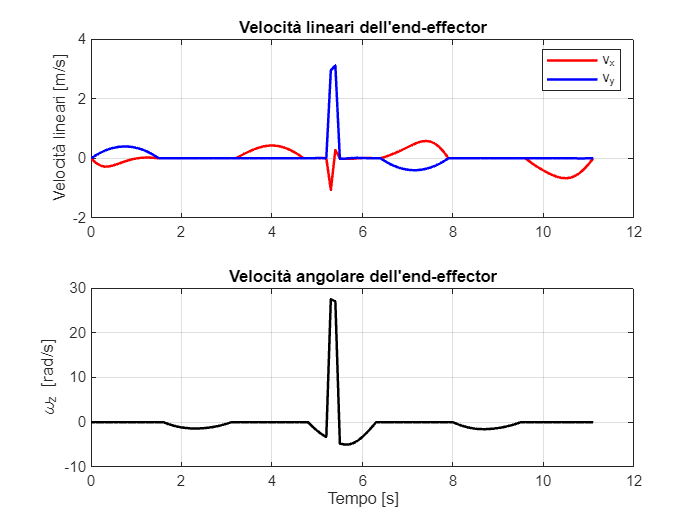

[angoli_totali] = [angoli; angoli2; angoli3;angoli4;angoli5;angoli6;angoli7];
vel = vel(:,1:3);
vel2 = vel2(:,1:3);
vel3 = vel3(:,1:3);
vel4 = vel4(:,1:3);
vel5 = vel5(:,1:3); 
vel6 = vel6(:,1:3);
vel7 = vel7(:,1:3);
vel_totali = [vel;vel2;vel3;vel4;vel5;vel6;vel7];


function grafico_vel(vel, tempo)
    figure;
    subplot(2,1,1);
    plot(tempo, vel(:,1), 'r', 'LineWidth', 1.5); hold on;
    plot(tempo, vel(:,2), 'b', 'LineWidth', 1.5);
    ylabel('Velocità lineari [m/s]');
    legend('v_x','v_y'); grid on;
    title('Velocità lineari dell''end-effector');

    subplot(2,1,2);
    plot(tempo, vel(:,3), 'k', 'LineWidth', 1.5);
    ylabel('\omega_z [rad/s]');
    xlabel('Tempo [s]');
    title('Velocità angolare dell''end-effector');
    grid on;
end



grafico_vel(vel_totali, tempo_totale)

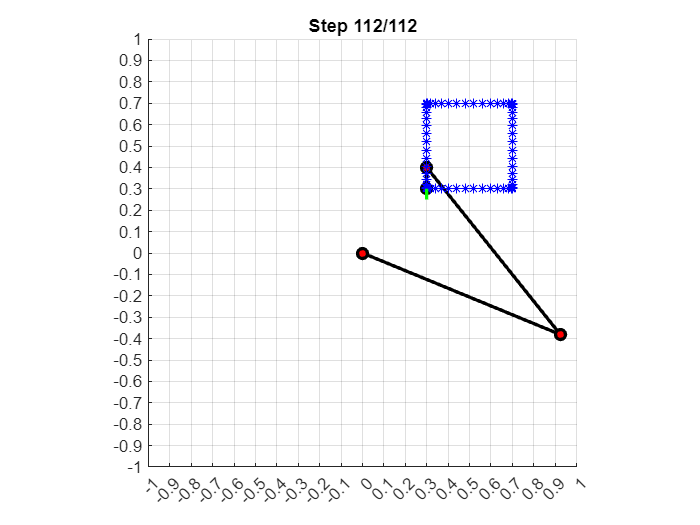

animazione_robot_planare(angoli_totali, l1, l2, l3);